# Mie Scattering

**Eran Ofek**

This document provides some examples on how to use the mie scattering routines by Jan Schäfer.

Some good references to Mie scattering:

[https://opg.optica.org/josa/fulltext.cfm?uri=josa-52-4-402&id=76016](https://opg.optica.org/josa/fulltext.cfm?uri=josa-52-4-402&id=76016)

[https://www.ess.uci.edu/~cmclinden/link/xx/node19.html](https://www.ess.uci.edu/~cmclinden/link/xx/node19.html)

and online calculator:

[https://omlc.org/cgi-bin/mie_angles.cgi?diameter=2&lambda_vac=2&n_medium=1.0&nr_sphere=1.5&ni_sphere=0&n_angles=180&density=0.1](https://omlc.org/cgi-bin/mie_angles.cgi?diameter=2&lambda_vac=2&n_medium=1.0&nr_sphere=1.5&ni_sphere=0&n_angles=180&density=0.1)

% refreactive index for alpha-Si O2 (quartz)
Lambda = 0.5

Lambda =           0.5


A = 1.29605832

A =        1.2961


B = 1.06065833;
C = 1.01235833./100;
D = 2.25605819;
E = 200;
n2 = A + B./(1-C./Lambda.^2) + D./(1-E./Lambda.^2)

n2 =        2.3987



RAD = 180./pi;
r=0.5;  % particle radius
n = 1.5;   % refractive index (silicate)
%Lambda = 0.5;
k      = 2.*pi./Lambda;  % wave number
a      = 2.*pi.*r./Lambda;

[S, C, ANG] = calcmie(r, n, 1, Lambda, 180, 'ConvergenceFactor',1);
% Equation 3 in REF 1:
S1=squeeze(abs(S(1,1,:))).^2;
S2=squeeze(abs(S(2,2,:))).^2;


%The flux scattered by one particle per unit solid angle in the direction θ divided
% by the flux incident on the geometrical cross section (πr2) of the spherical particle;
% its dimension is 1/sr.
Itheta = (2.*pi.*a.^2).^-1 .*(S1+S2);

% K is defined as the ratio of the total scattered flux to the incident flux
K = 2.*pi.*trapz(ANG(:)./RAD, Itheta.*sind(ANG(:)))

K =        2.3505



% to calculate the angular Mie cross section
% Note that there is an error in Eq. 8 in REF 1 - should be ^-1 instead of
% ^-2
SigmaTheta = pi.*r.^2 .* Itheta;  % units of area/sr

% to verify the total cross section:
% THIS IS WROMG !
%TotalCrossSection = Lambda.^2./(4.*pi) .* trapz(ANG(:)./RAD,  2.*pi.*sind(ANG(:)).*(S1+S2))

TotalCrossSection =        11.599


% CORRECT
TotalCrossSection = 2.*pi.*trapz(ANG(:)./RAD, SigmaTheta.*sind(ANG(:)))

TotalCrossSection =        1.8461




% and this is like:
C.sca

ans =        1.8468



Itheta(1)./(pi.*r.^2)

ans =        6.7415


Itheta(91)./(pi.*r.^2)

ans =      0.053374


PWD = pwd;
cd /home/eran/matlab/data/spec/Sun/
load SunSpec.mat
cd(PWD);

astro.spec.synthetic_phot(SunSpec,'Swift/UVOT','UVW2','Vega')

ans =       -23.172


astro.spec.synthetic_phot(SunSpec,'GAIA','Bp','Vega')

ans =       -26.743


% Didymos Albedo in the UV is 1./2.2 of its Bp albedo


Fz = AstFilter.get('SDSS','z');
Fz = Fz.nT;
Fz(:,1) = Fz(:,1)./1e4;  % microns

Fuv = AstFilter.get('Swift/UVOT','UVW2');
Fuv = Fuv.nT;
Fuv(:,1) = Fuv(:,1)./1e4;  % microns
Fb  = [200 0; 340 0; 350 0.05; 400 0.4; 500 0.9; 600 0.65; 700 0.45; 800 0.2; 1000 0.0]

Fb =           200            0
          340            0
          350         0.05
          400          0.4
          500          0.9
          600         0.65
          700         0.45
          800          0.2
         1000            0


Fb(:,1) = Fb(:,1)./1000; % microns

Fz(:,2)  = Fz(:,2)./max(Fz(:,2));
Fuv(:,2) = Fuv(:,2)./max(Fuv(:,2));
Fb(:,2)  = Fb(:,2)./max(Fb(:,2));

%Fuv(:,2) = Fuv(:,2)./trapz(Fuv(:,1),Fuv(:,2));
%Fb(:,2)  = Fb(:,2)./trapz(Fb(:,1),Fb(:,2));
%Fz(:,2)  = Fz(:,2)./trapz(Fz(:,1),Fz(:,2));

rVec = logspace(-2,1,100); %(0.01:0.01:6).';
Nr   = numel(rVec);
lVec = (0.1:0.05:1).';
Nl   = numel(lVec);

FilterUV = interp1(Fuv(:,1),Fuv(:,2),lVec);
FilterB  = interp1(Fb(:,1),Fb(:,2),lVec);
FilterZ  = interp1(Fz(:,1),Fz(:,2),lVec);

n = 1.5 + 1i.*0.3

n =           1.5 +        0.3i


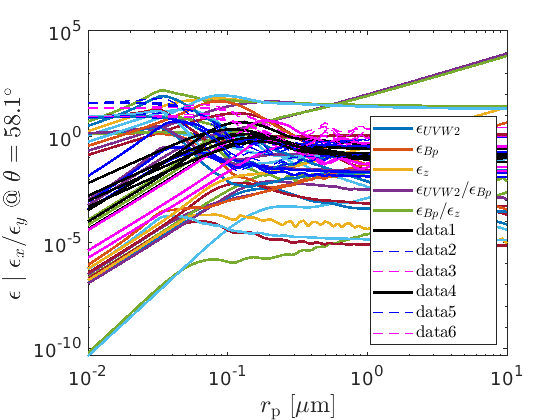

%n = 1.7 + 1i.*0.03
%n = 1.7 + 1i.*0.003

SigmaTheta = zeros(Nr,Nl);
IthetaMat  = zeros(Nr,Nl);
epsilon_abs = zeros(Nr,Nl);
for Ir=1:1:Nr
    for Il=1:1:Nl
        r = rVec(Ir);
        Lambda = lVec(Il);
        k      = 2.*pi./Lambda;  % wave number
        a      = 2.*pi.*r./Lambda; % size parameter (alpha)
        
        [S, C, ANG] = calcmie(r, n, 1, Lambda, 180, 'ConvergenceFactor',1);
        % Equation 3 in REF 1:
        S1=squeeze(abs(S(1,1,:))).^2;
        S2=squeeze(abs(S(2,2,:))).^2;
        % Note that there is an error in Eq. 8 in REF 1 - should be ^-1 instead of
        % ^-2
        Itheta = (2.*pi.*a.^2).^-1 .*(S1 + S2);
        
        % to calculate the angular Mie cross section
        
        IthetaT = interp1(ANG(:),Itheta(:), 58.1);
        
        epsilon_abs(Ir,Il) = C.abs./(pi.*r.^2);
        
        IthetaMat(Ir,Il) = IthetaT; %
        %SigmaTheta(Ir,Il) = pi.*r.^2 .* IthetaT;  % units of area/sr

        
    end
    
end


RU = nansum(IthetaMat.*FilterUV.',2).*4.*pi;
RB = nansum(IthetaMat.*FilterB.',2).*4.*pi;
RZ = nansum(IthetaMat.*FilterZ.',2).*4.*pi;

EpsAbsB = nansum(epsilon_abs.*FilterB.',2);

%RU = nansum(Albedo.*FilterUV.',2);
%RB = nansum(Albedo.*FilterB.',2);

%loglog(rVec,RU,'LineWidth',2,'Color','b')
loglog(rVec,RB./EpsAbsB,'LineWidth',2,'Color','k')
hold on;
%loglog(rVec,RZ,'LineWidth',2,'Color','m')

loglog(rVec, RU./RB,'b--','LineWidth',1)
loglog(rVec, RB./RZ,'m--','LineWidth',1)



H = xlabel('$r_{\rm p}$ [$\mu$m]')

H =   Text ($r_{\rm p}$ [$\mu$m]) with properties:

                 String: '$r_{\rm p}$ [$\mu$m]'
               FontSize: 18
             FontWeight: 'normal'
               FontName: 'times'
                  Color: [0.15 0.15 0.15]
    HorizontalAlignment: 'center'
               Position: [0.31623 9.1428e-13 -1]
                  Units: 'data'

  Show all properties


H.Interpreter = 'latex';
H.FontSize    = 18;
H = ylabel('$\epsilon$ $\vert$ $\epsilon_{x}/\epsilon_{y}$ @ $\theta=58.1^{\circ}$')

H =   Text ($\epsilon$ $\vert$ $\epsilon_{x}/\epsilon_{y}$ @ $\theta=58.1^{\circ}$) with properties:

                 String: '$\epsilon$ $\vert$ $\epsilon_{x}/\epsilon_{y}$ @ $\theta=58.1^{\circ}$'
               FontSize: 18
             FontWeight: 'normal'
               FontName: 'times'
                  Color: [0.15 0.15 0.15]
    HorizontalAlignment: 'center'
               Position: [0.0037625 0.0021026 -1]
                  Units: 'data'

  Show all properties


H.Interpreter = 'latex';
H.FontSize    = 18;

H = legend('$\epsilon_{UVW2}$','$\epsilon_{Bp}$','$\epsilon_{z}$','$\epsilon_{UVW2}/\epsilon_{Bp}$','$\epsilon_{Bp}/\epsilon_{z}$','Location','SouthEast')

H =   Legend ($\epsilon_{UVW2}$, $\epsilon_{Bp}$, $\epsilon_{z}$, $\epsilon_{UVW2}/\epsilon_{Bp}$, $\epsilon_{Bp}/\epsilon_{z}$) with properties:

         String: {'$\epsilon_{UVW2}$'  '$\epsilon_{Bp}$'  '$\epsilon_{z}$'  '$\epsilon_{UVW2}/\epsilon_{Bp}$'  '$\epsilon_{Bp}/\epsilon_{z}$'}
       Location: 'southeast'
    Orientation: 'vertical'
       FontSize: 12.6
       Position: [0.66091 0.17751 0.2256 0.25179]
          Units: 'normalized'

  Show all properties


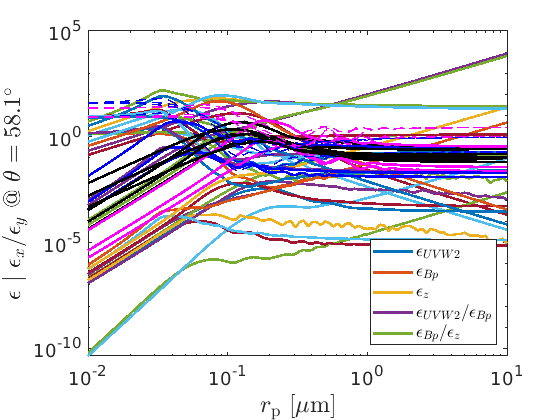

H.Interpreter = 'latex';

print MieScattering_Example.eps -depsc2